clear all ;clc
global L B d0_h mu A y d0_h rho N

table = zeros(20,20);
L = 128;
times = 2000;
for i = 1:20
    for j = 1:20
        N = i*5;
        K = j*5;
        mu = 6*sqrt(L/(K+N))/log(L);
        [y,B,A,h,x,C] = createorigin(L,N,K);
        Astar = compute_Astar(y);
        [d0_h,h0_h,x0_h] = estimate(Astar);
        rho = d0_h^2/100;
        step = 1/((N*log(L)+ rho*L/(mu^2)));
        [u0,v0] = optimizer(d0_h,h0_h,x0_h);
        [u,v] = updategradient(u0,v0,step,times);
        table(i,j) = isvalid(h,x,u,v);
    end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

end

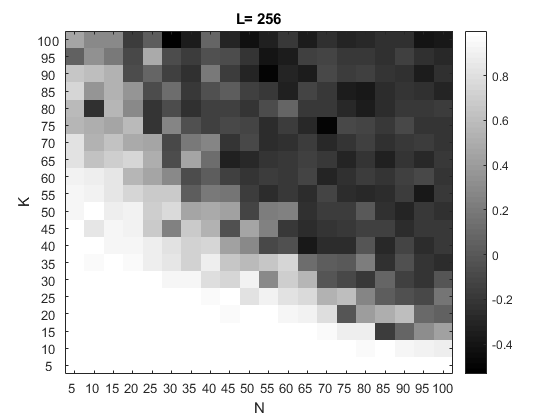

imagesc(1-table);
set(gca,'YDir','normal');
colormap gray
title('L= 256');
xlabel('N')
ylabel('K')
set(gca,'xtick',[1:20],'xticklabel',[5:5:100])
set(gca,'ytick',[1:20],'yticklabel',[5:5:100])
colorbar

function [c,ceq] =constaint(u0)
    global L B d0_h mu
    c = sqrt(L).*norm(B*u0,'Inf')-2*sqrt(d0_h)*mu;
    ceq = [];
end
function [y,B,A,h,x,C] = createorigin(L,N,K)
    F = dftmtx(L)/sqrt(L);
    B = F(:,1:K);
    h = randn(K,1);
    h = h/norm(h);
    C = randn(L,N)+1i*randn(L,N);
    A = F*C;
%     A = randn(L,N)+1i*randn(L,N);
    x = randn(N,1);
    x = x/norm(x);
    y =diag(B*h*x'*A');
%     y =diag(B*h)*(A*conj(x)); 
end
function Astar = compute_Astar(y)
    global A B L
    Astar = zeros(size(B,2),size(A,2));
    A_star = A';
    B_star = B';
    for i = 1:length(y)
        Astar = Astar + y(i).* B_star(:,i)*A_star(:,i)';        
    end
end
function Aoirgin = compute_Aorigin(Z) 
    global A B
    Aoirgin = diag(B*Z*A');
end
function [d0_h,h0_h,x0_h] = estimate(Astar)
    [u,s,v] = svd(Astar);
    d0_h =  s(1,1);
    h0_h = u(:,1);
    x0_h = v(:,1);
end
function [u0,v0] = optimizer(d0_h,h0_h,x0_h)
    global L mu B
    fun = @(z)norm(z-sqrt(d0_h).*h0_h)^2;
    z0 = randn(length(h0_h),1);
    nonlcon = @constaint;
    u0 = fmincon(fun,z0,[],[],[],[],[],[],nonlcon);
    v0 = sqrt(d0_h)*x0_h;
end
function res = helper(h)
    global B mu L N d0_h
    B_star = B';
    res = zeros(size(B,2),1);
    for i =1 : L
        res = res + g0_p(L*abs(B_star(:,i)'*h)^2/(8*d0_h*mu^2))*B_star(:,i)*B_star(:,i)'*h;
    end
end
function res = g0_p(x)
    res = 2*sqrt(max(x-1,0)^2);
end
function [dh,dx] = compute_gradient(h,x)
    global mu y d0_h rho
    dfh = compute_Astar(compute_Aorigin(h*x')-y)*x;
    dfx = compute_Astar(compute_Aorigin(h*x')-y)'*h;
    dgh = rho/2/d0_h*((g0_p(norm(h)^2/2/d0_h))*h + length(y)/(4*mu*mu)*helper(h));
    dgx = rho/2/d0_h *(g0_p(norm(x)^2/2/d0_h))*x;
    dh = dfh + dgh;
    dx = dfx + dgx;
end
function [u,v] = updategradient(u0,v0,step,times)
    u = u0;
    v = v0;
    for i = 1:times
        [du,dv] = compute_gradient(u,v);
        u = u - step*du;
        v = v - step*dv;
    end
end
function error = isvalid(h,x,u,v)
    error = norm(h*x'-u*v','fro')/norm(u*v','fro');
end